clear all;
close all;

**Giordano Dylan - Martelet Curtis                            L3 EEA_Gr TP1**


Ve=30;

# Rapport TDP4: Hacheur parallèle

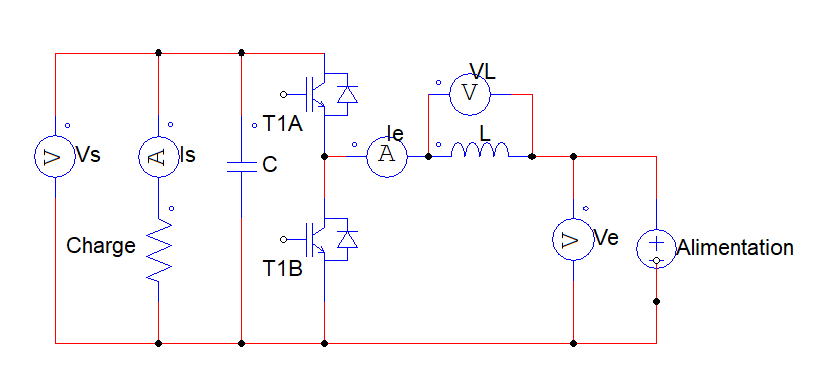

*Schéma de cablage du bloc de puissance en mode "Hacheur parallele".*

## 2. Etude de la fonction de conversion

### Mesures de valeurs moyennes

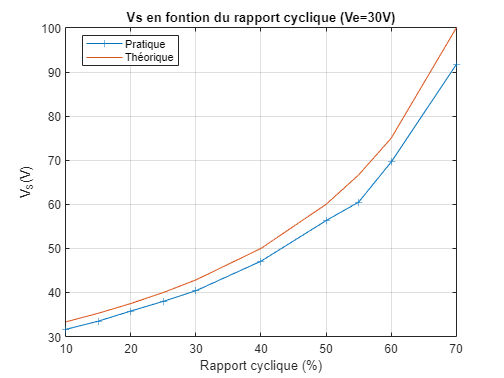

alpha=[0.1 0.15 0.20 0.25 0.30 0.40 0.50 0.55 0.60 0.70]*100;
Vs=[31.63 33.5 35.8 38 40.4  47.1 56.3 60.5 69.6 91.7];


Ie=[1.44 1.52 1.62 1.74 1.89 2.21 2.61 2.91 3.32 4.51];
Is=[1.29 1.29 1.29 1.30 1.32 1.31 1.29 1.30 1.30 1.31];

Ps=Vs.*Is;
Pe=Ve.*Ie;

Vsth=(100.*Ve)./(100-alpha);%%Pour avoir alpha en pourcentage en absscice, il faut multiplier la formulule par cent au dénominateur et au numérateur
rendement_th=[100 100 100 100 100 100 100 100 100 100];

plot(alpha,Vs,'+-',alpha,Vsth);
title("Vs en fontion du rapport cyclique (Ve=30V)");
xlabel("Rapport cyclique (%)"); ylabel("V_S(V)");
legend('Pratique','Théorique','Location','best');
grid on;

On peut observer que l'allure de la courbe de la tension Vs en fonction du rendement pour un Ve constant est identique à celle pour le hacheur série dans les mêmes circonstances.

En effet, on a Vs = (1+α)*Ve. Nous n'avons pas tracé pour un rapport cyclique nul car Vs est également nul. Aussi, utilisé un rendement supérieur à 70% risquait de détruire le bloc de puissance, c'est pourquoi nous nous sommes arretés à 70%.

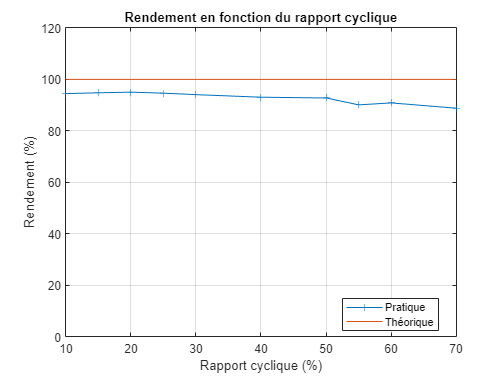

plot(alpha,Ps./Pe *100,'+-',alpha,rendement_th);
title("Rendement en fonction du rapport cyclique");
xlabel("Rapport cyclique (%)"); ylabel("Rendement (%)");
legend('Pratique','Théorique','Location','best');
ylim([0 120])
grid on;

Puisque le bloc de convertion est un hacheur, alors il est normal d'avoir rendement quasi-constant. On peut néanmoins observer que le rendement du hacheur élévateur est supérieur à celui d'un hacheur abaisseur.

Aussi, on peut observer que plus le rapport cyclique est élevé, plus le rendement diminue.

(`Hypothèse`) La cause est la même que pour la courbe du rendement en fonction du rapport cyclique, c'est-à-dire que plus α est élevé, plus Us est grand et plus le bloc de puissance a de problème.

%%%Dire quel type de transistors il s'agit.

### Mesures temporelles

Orange -> U ; Vert -> iL. Le rapport cyclique est d'environ 20%. Ue = 30V.

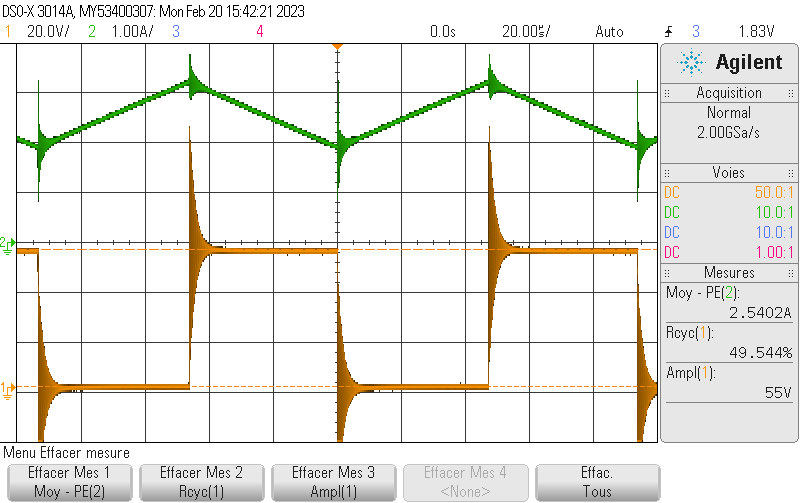

**On peut observer le fonctionnement normal du hacheur.**

- **De 0 à αT**, le transistor 1 et la diode 2 sont passants. On observe U=0 et le courant iL charge (la bobine se charge).

- **De αT à T**, le transistor 2 et la diode 1 sont passants. On observe U=Ue et le courant iL se décharge (la bobine se décharge).

Les "pics" que l'on observe sur les deux courbes sont provoqués par les commutations des transistors.

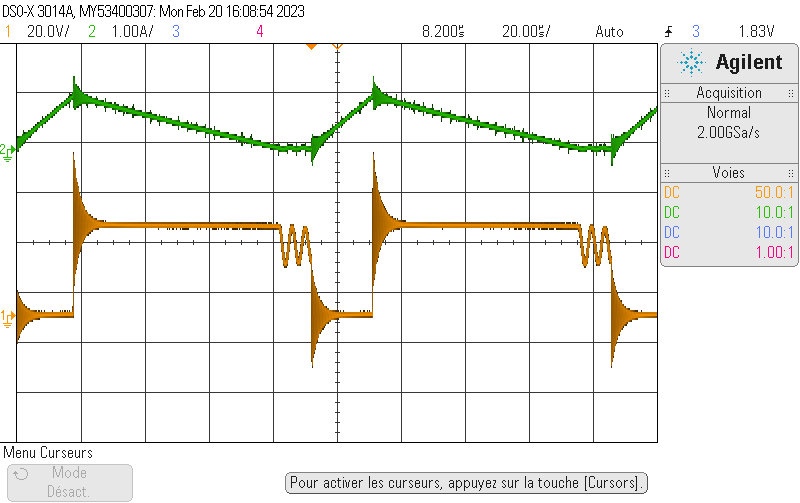

**Sur cet capture d'oscilloscope, on peut observer le fonctionnement en Conduction Discontinue**.

Comme pour le hacheur série, ce mode de conduction est a éviter: la tension moyenne de Us et de U se retrouvent modifier (négativement). Ce mode est due au courant trop faible, ce qui fait que la bobine n'a pas le temps de se charger complètement. 

## 3. Etude du filtre d'entrée

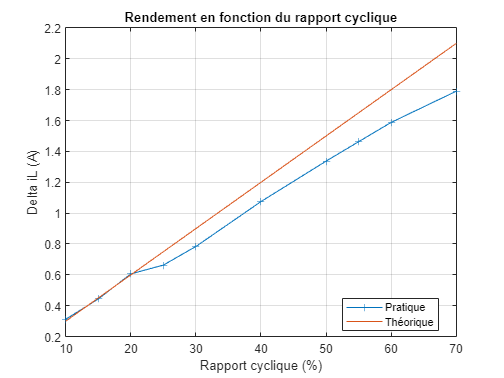

alpha=[0.1 0.15 0.20 0.25 0.30 0.40 0.50 0.55 0.60 0.70]*100;
Delta_iL=[312.5 443.75 606.25 663.25 784 1075 1337 1463 1588 1790]*1e-3;
Delta_il_th=((alpha./100).*Ve)./(1e-3*10e3);

plot(alpha,Delta_iL,'+-',alpha,Delta_il_th);
legend('Pratique','Théorique','Location','best');
title("Rendement en fonction du rapport cyclique");
xlabel("Rapport cyclique (%)"); ylabel("ΔiL (A)");
grid on

Les valeurs expérimentales ont la même allure que les valeurs théoriques, mais dévient plus le rapport cyclique augmente.

Plus le rapport cyclique est élevé, plus la différence entre la tension max et min de iL est élevé. Quand α augmente, la tension Us augmente également et donc réciproquement, le courant iL augmente. Le ΔiL est également amplifié. 

(`Hypothèse`) La cause est la même que pour la courbe du rendement en fonction du rapport cyclique, c'est-à-dire que plus α est élevé, plus Us est grand et plus le bloc de puissance a de problème.

### Allure de la courbe:

On peut voir sur les formes d'ondes que iL(t) est la dérivé de u(t) avec la relation: $I_L \left(t\right)=\frac{L\times \mathrm{du}\left(t\right)}{\mathrm{dt}}$ 

Comme  $\Delta I_L =\frac{V_e }{L}\times \Delta t=\frac{V_e \times \alpha \times T}{L}$, on a une relation entre $\Delta I_L$ et le rapport cyclique α de la forme $Y+\mathrm{Ax}$ avec:


$$A=$$

$$\frac{V_e \times \alpha \times T}{L}$$



$$Y=\Delta I_L$$



$$X=\alpha$$


## 4. Etude qualitative du fonctionnement

%%% A modifier pour adapter au hacheur parallele

On modifie uniquement un seul des paramètres a la fois :

- **Rapport cyclique :** faire varier le rapport cyclique fait varier egalement la tension de sortie avec la relation : Vs=Ve/(1-α)

- **Ve :** faire varier la tension d'entree fera egalement varier la tension de sortie. Pour le hacheur élévateur, Ve<=Vs.

- **R :** faire varier la charge changera la valeur du courant Is.

- **Fe :** modifier la frequence de decoupage aura un impact sur la qualite du signal en sortie du hacheur.Plus la frequence sera faible, plus le regime transitoire (conduction discontinue) sera apparent sur le signal (signal en dent de scie).

- **L : **enfin, modifier L aura le même effet que de faire varier Fe. La diminuer fera qu'elle ne pourra lisser correctement, et donc rendra les creneaux visibles (conduction discontinue) ==> (signal en dent de scie). 

## 5. Complément: Conduction discontinue

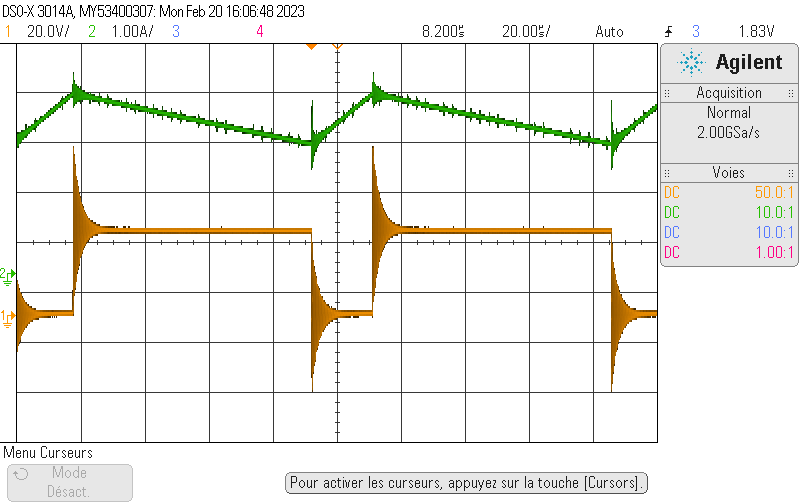

Mode de fonctionnement normal.

Mode de fonctionnement discontinue.

Pour les mesures, nous prenons un rapport cyclique de 20%.

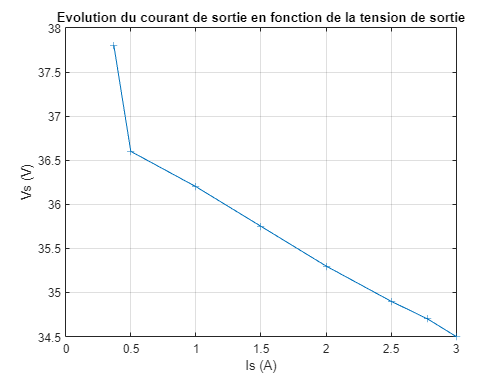

Is = [3 2.78 2.5 2 1.5 1 0.5 0.37];
Vs = [34.5 34.7 34.9 35.3 35.75 36.2 36.6 37.8];

plot(Is,Vs,"+-");
title("Evolution du courant de sortie en fonction de la tension de sortie");
xlabel("Is (A)"); ylabel("Vs (V)");
grid on

Dans cette dernière partie, on fait varier la valeur de R tout en gardant un α (=20%) et un Ve (30V) constant. On observe que Vs est inversement proportionnel au courant Is, ce qui est normal puisque I = U/R et on fait varier R